# Examples Notebook

This notebook is going to be used to create the graphics for alot of the images used in chapter 2 of my thesis. The first two are going to be the correlation example and the TFD examples.

## Correlations

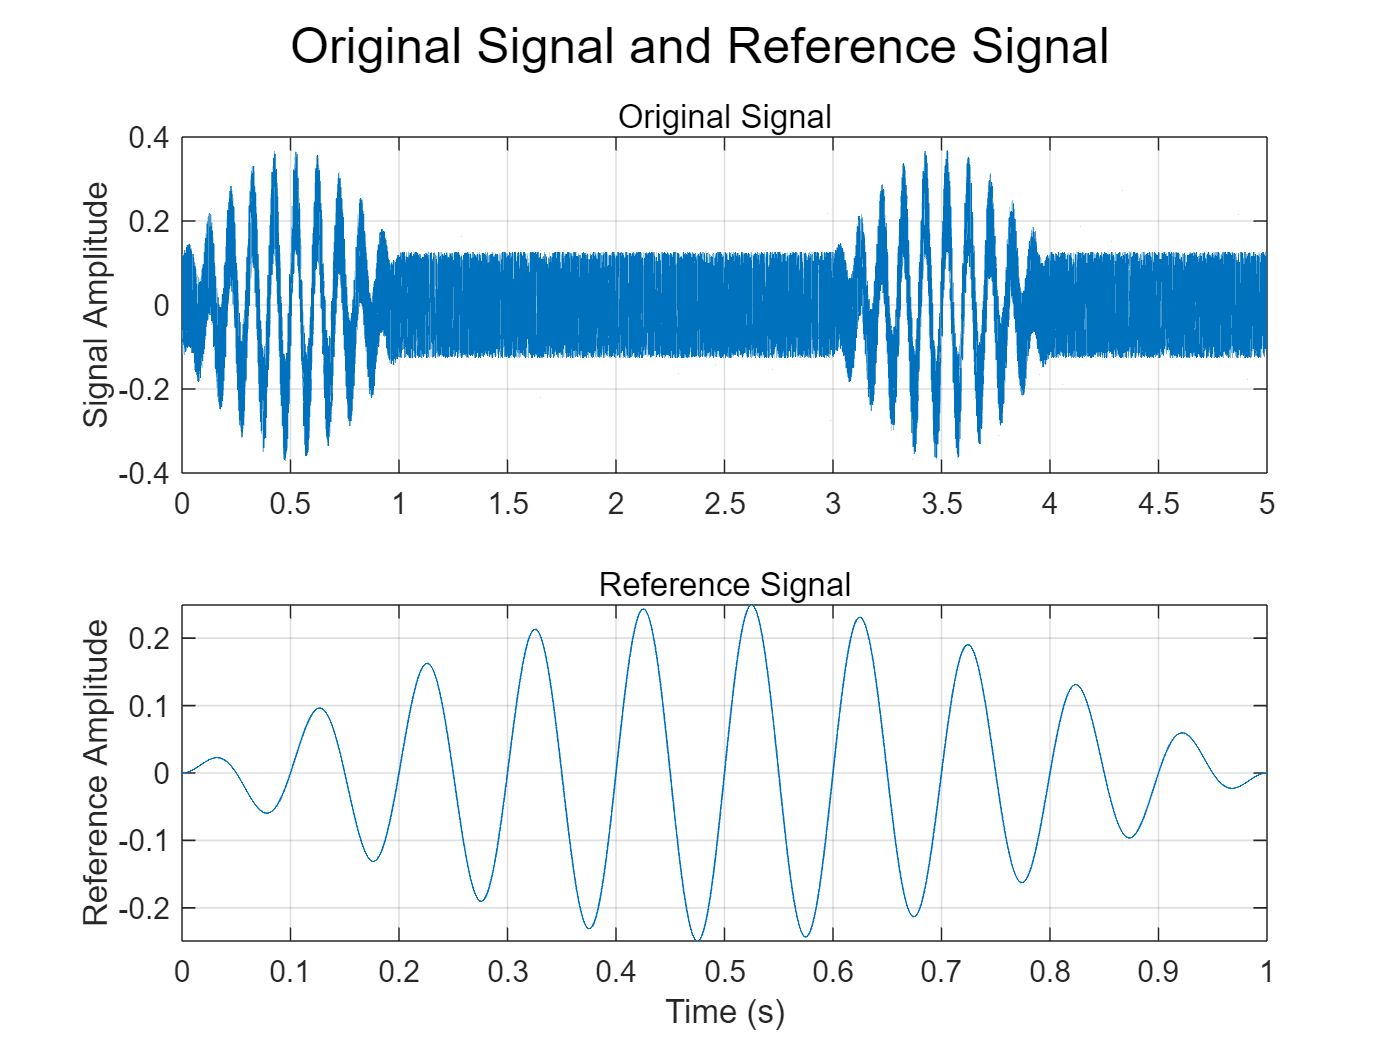

% --Setup
    clear; clc; format compact; close all; warning off;

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 0.25;
    envelope = amplitude.* sin(pi*t);
    signal = envelope .* sin(f*t);
    signal = [signal, zeros(1, 2*fs), signal, zeros(1, 1*fs-1)];
    noisy_signal = randi(100,1,length(signal))./400 + signal;
    signal = noisy_signal - mean(noisy_signal);

% --Zero pad signals to make same length
    diff = length(signal) - length(ref_signal);
    pad = zeros([1, diff]);
    ref_signal_long = [ref_signal, pad];

% --Plot original Signals
    figure()
    subplot(2,1,1)
    plot(t1, signal)
        hold on
        grid on
        subtitle("Original Signal")
        sgtitle("Original Signal and Reference Signal")
        ylabel('Signal Amplitude')

    subplot(2,1,2)
    plot(t, ref_signal)
        hold on
        grid on
        xlabel('Time (s)')
        ylabel('Reference Amplitude')
        subtitle('Reference Signal')

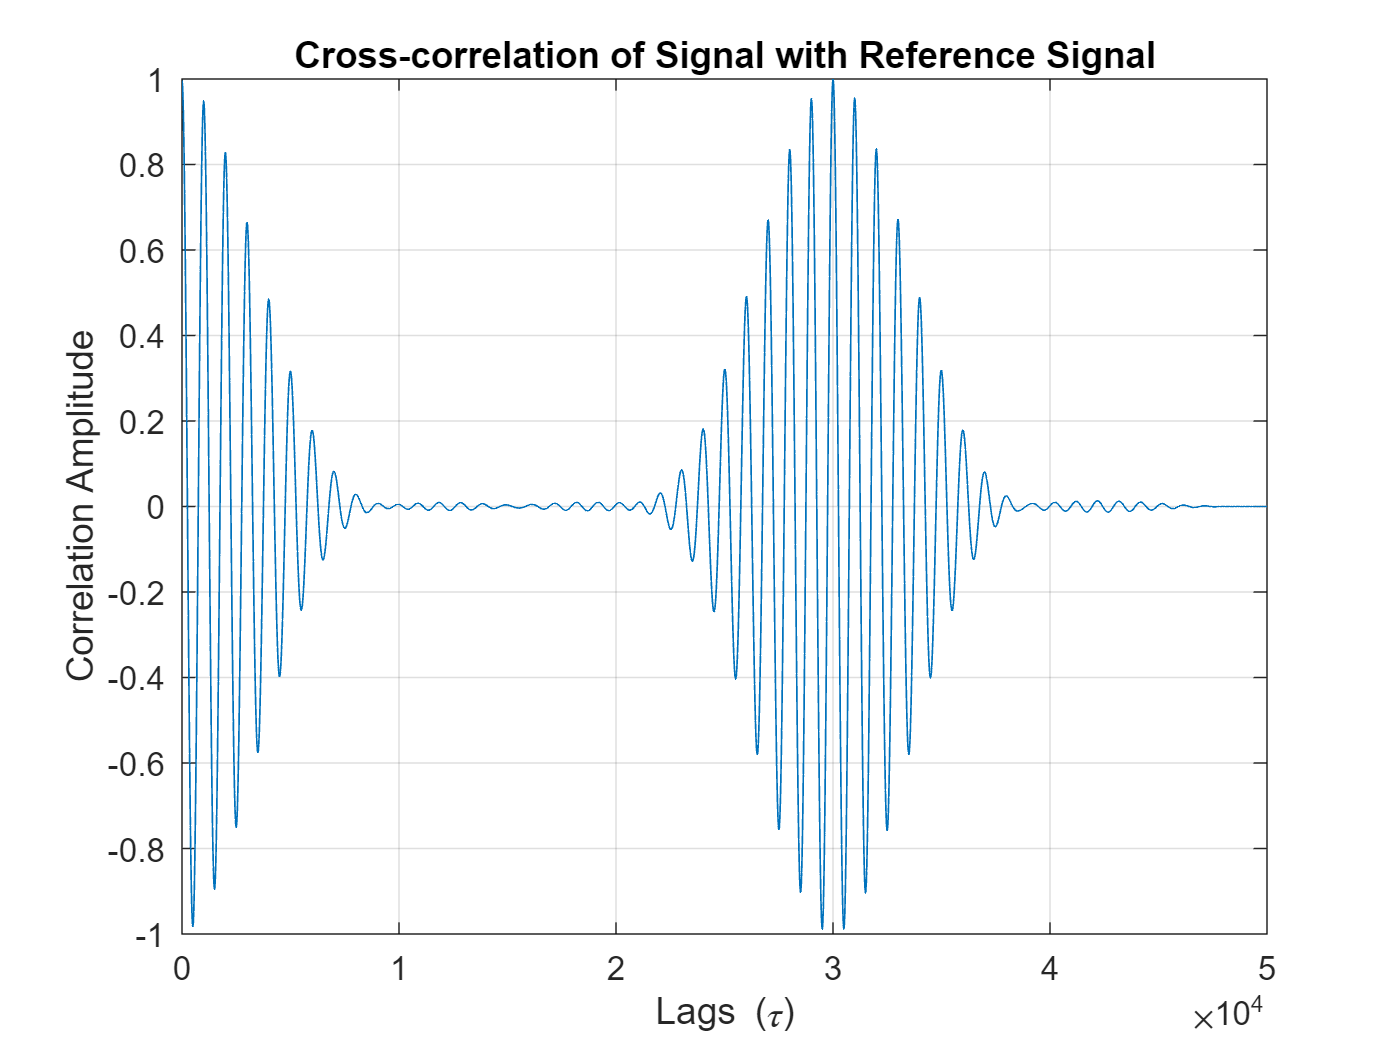

% --Find DFT of signals
    f_signal = fft(signal);
    f_ref_sig = fft(ref_signal_long);

% --Find corr
    corr = f_signal .* conj(f_ref_sig);
    corr = ifft(corr);
    corr = corr - min(corr);
    corr = corr ./ max(corr);

% --calling xcorr function
    corr2 = xcorr(signal, ref_signal);
    corr2 = corr2(length(signal):2*length(signal) -1 );
    corr2 = corr2 ./ max(corr2);
    

% --Plot correlation
    figure()
    plot(corr2)
    hold on
    grid on
    xlabel('Lags (\tau)')
    xlim([0 length(signal)])
    ylabel('Correlation Amplitude')
    title('Cross-correlation of Signal with Reference Signal')

## Spectrograms and TFD

% --Create Chirps
    figure()
    chirp = create_chirp("logarithmic", 1, 0.5, 300, 4000, 10000, "true");

Default Spectrogram Settings Used


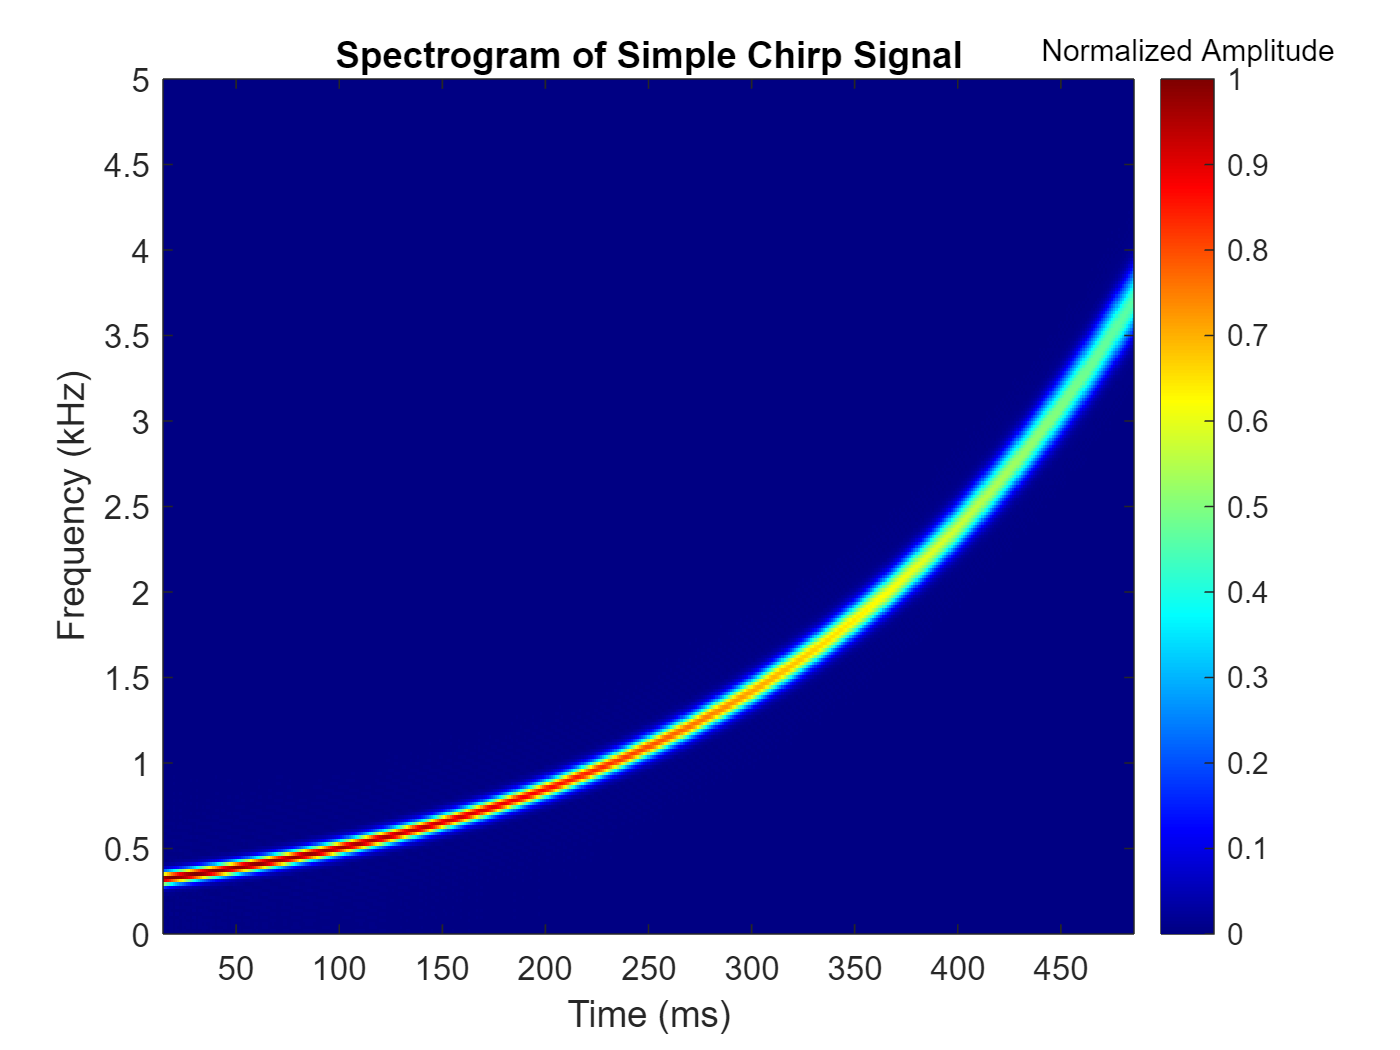

    title("Spectrogram of Simple Chirp Signal")

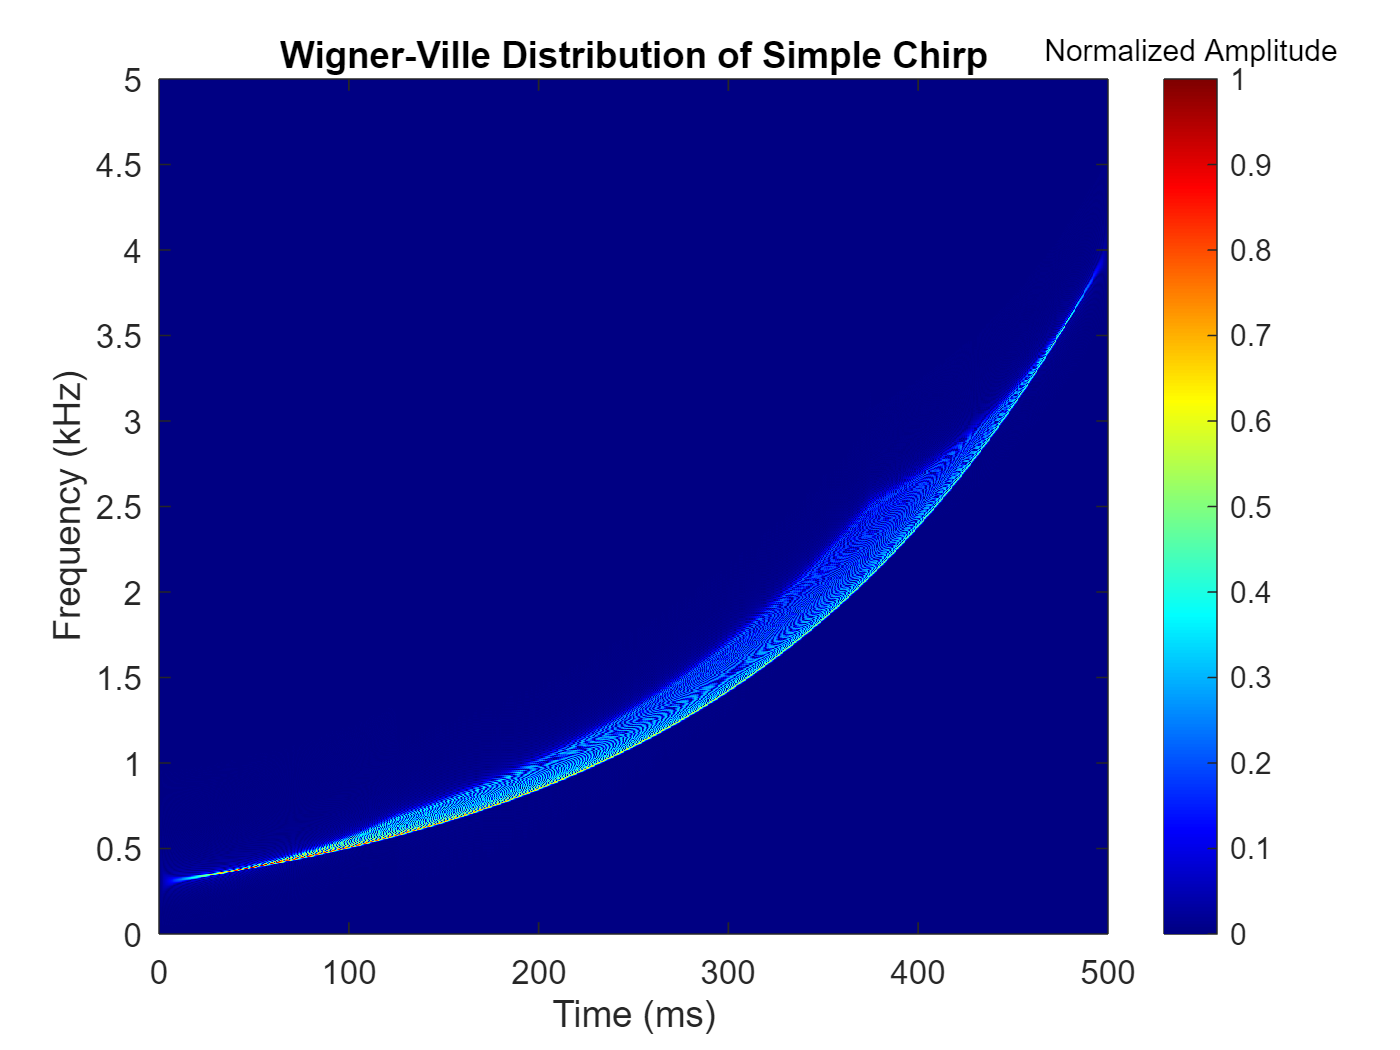

% --Find WVD of chirp
    [s, f, t] = wvd(chirp, 10000);
        s = abs(s);
        s = s - min(min(s));
        s = s ./ max(max(s));
        t = t .* 1000;
        f = f ./ 1000;

% --Make image
    figure()
    imagesc(t,f,s)
        set(gca,"YDir","normal")
        colormap('jet')
        clb = colorbar;
        title('Unfiltered Spectrogram of Data')
        xlabel('Time (ms)');
        ylabel('Frequency (kHz)')
        clb.Title.String = "Normalized Amplitude";
        maxf = max(max(f));
        minf = min(min(f));
        ylim([minf maxf])
        xlim([0 500])
        title("Wigner-Ville Distribution of Simple Chirp")